mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122


x0 = [0.803317447531649	0 0 0.333418772378925]

x0 =     0.8033         0         0    0.3334


C1 = jacobiConstant([0.803317447531649	0],[0 0.333418772378925],mu)

C1 = 3.0946

periodoUnstable = 3.20588680682668;

options=odeset('RelTol',1e-12,'AbsTol',1e-22);

[t,Xp]=ode113(@CRTBPForward,[0 periodoUnstable],x0,options,mu);
Xp(end,:)

ans =     0.8033    0.0000   -0.0000    0.3334



diferencia = x0 - Xp(end,:)

diferencia = 	1.0e+-4 *

    0.1499   -0.0706    0.3248   -0.1463


vpa(diferencia)

$$ans = \left(\begin{array}{cccc} 0.000014985710087955794733716174960136 & -0.000007056782431511238846359029830424 & 0.000032480604288708916417040273305616 & -0.000014625659463085582956409780308604 \end{array}\right)$$

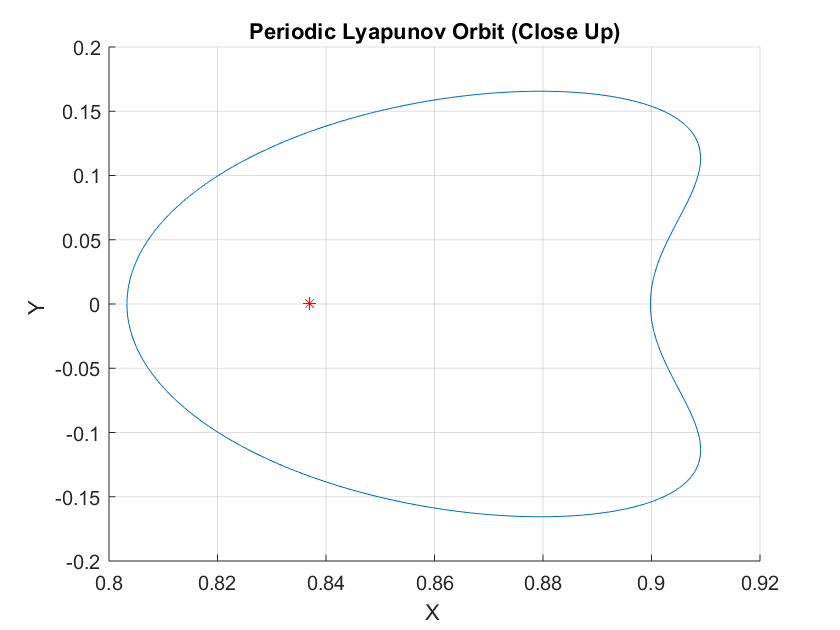

L = 0.836915;
tPeriodo = plotPeriodicOrbit(x0,periodoUnstable,mu,L);